题（2）

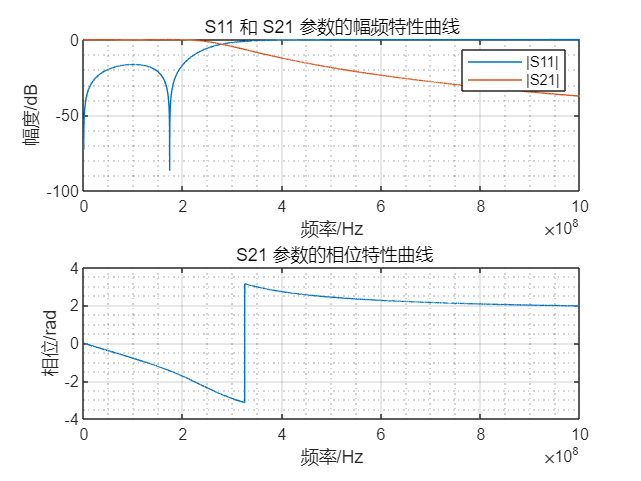

clear;clc;
%%%%%%%%%%%%%%%%%%%实验条件%%%%%%%%%%%%%%%%%%%
L1 = 45.6e-9;% 单位：亨利
C1 = 16.4e-12;% 单位：法拉
f=0:1e5:1e9;
%%%%%%%%%%%%%%%%%%%计算矩阵%%%%%%%%%%%%%%%%%%%
A=1-(2*pi*f).^2*L1*C1;
B=1j*2*pi*f*L1;
C=2j*2*pi*f*C1-1j*(2*pi*f).^3*L1*C1.^2;
D=A;
[S11_1,S12_1,S21_1,S22_1]=A2S(50,A,B,C,D);
%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%
figure();
subplot(2,1,1);
plot(f,20*log10(abs(S11_1)),f,20*log10(abs(S21_1)));
title('S11 和 S21 参数的幅频特性曲线');
xlabel('频率/Hz');ylabel('幅度/dB');
legend('|S11|','|S21|');
grid on;grid minor;

subplot(2,1,2);
plot(f,angle(S21_1));
title(' S21 参数的相位特性曲线');
ylabel('相位/rad');
xlabel('频率/Hz');
grid on;grid minor;

题（3）

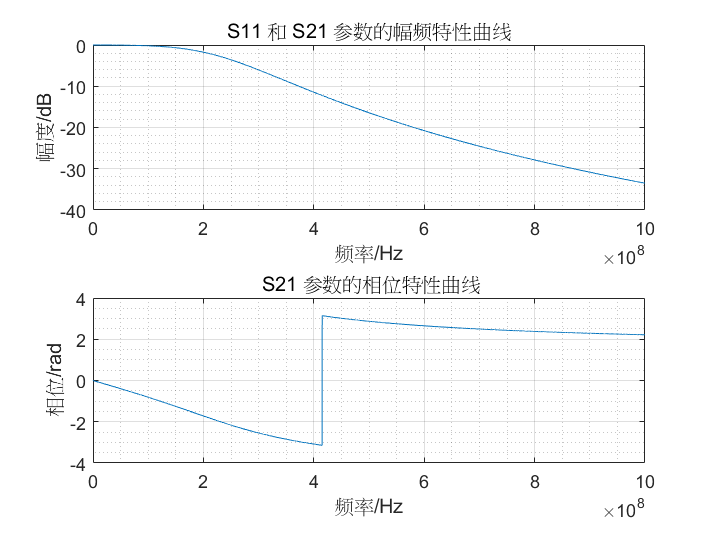

%%%%%%%%%%%%%%%%%%%改变Z0再绘制%%%%%%%%%%%%%%%%%%%
[S11_2,S12_2,S21_2,S22_2]=A2S(30,A,B,C,D);
figure();
subplot(2,1,1);
plot(f,20*log10(abs(S21_2)));
title('S11 和 S21 参数的幅频特性曲线');
xlabel('频率/Hz');
ylabel('幅度/dB');
grid on;grid minor;

subplot(2,1,2);
plot(f,angle(S21_2));
title(' S21 参数的相位特性曲线');
ylabel('相位/rad');
xlabel('频率/Hz');
grid on;grid minor;

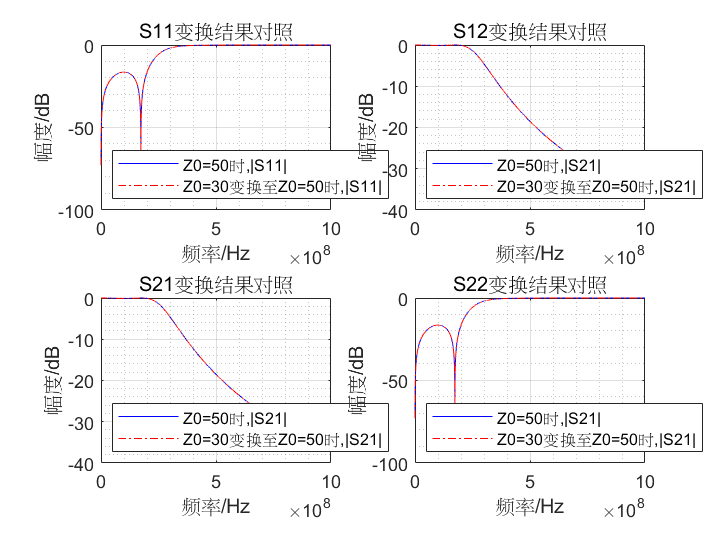

%%%%%%%%%%%%%%%%%%%验证变换%%%%%%%%%%%%%%%%%%%
z11=((1+S11_2).*(1-S22_2)+S21_2.*S12_2)./((1-S11_2).*(1-S22_2)-S21_2.*S12_2);
z12=2.*S12_2./((1-S11_2).*(1-S22_2)-S21_2.*S12_2);
z21=2.*S21_2./((1-S11_2).*(1-S22_2)-S21_2.*S12_2);
z22=((1-S11_2).*(1+S22_2)+S21_2.*S12_2)./((1-S11_2).*(1-S22_2)-S21_2.*S12_2);
Z11=z11.*30./50;
Z12=z12.*30./50;
Z21=z21.*30./50;
Z22=z22.*30./50;
[S11_3,S12_3,S21_3,S22_3]=Z2S(Z11,Z12,Z21,Z22);
figure();
subplot(2,2,1);
plot(f,20*log10(abs(S11_1)),'b',f,20*log10(abs(S11_3)),'-.r');
title('S11变换结果对照');
xlabel('频率/Hz');
ylabel('幅度/dB');
lgd=legend('Z0=50时,|S11|','Z0=30变换至Z0=50时,|S11|');
lgd.Location = 'southwest';
grid on;grid minor;
subplot(2,2,2);
plot(f,20*log10(abs(S12_1)),'b',f,20*log10(abs(S12_3)),'-.r');
title('S12变换结果对照');
xlabel('频率/Hz');
ylabel('幅度/dB');
lgd=legend('Z0=50时,|S21|','Z0=30变换至Z0=50时,|S21|');
lgd.Location = 'southwest';
grid on;grid minor;
subplot(2,2,3);
plot(f,20*log10(abs(S21_1)),'b',f,20*log10(abs(S21_3)),'-.r');
title('S21变换结果对照');
xlabel('频率/Hz');
ylabel('幅度/dB');
lgd=legend('Z0=50时,|S21|','Z0=30变换至Z0=50时,|S21|');
lgd.Location = 'southwest';
grid on;grid minor;
subplot(2,2,4);
plot(f,20*log10(abs(S22_1)),'b',f,20*log10(abs(S22_3)),'-.r');
title('S22变换结果对照');
xlabel('频率/Hz');
ylabel('幅度/dB');
lgd=legend('Z0=50时,|S21|','Z0=30变换至Z0=50时,|S21|');
lgd.Location = 'southwest';
grid on;grid minor;

function [S11,S12,S21,S22]=A2S(Z0,A,B,C,D)
    S11=(A+B./Z0-C*Z0-D)./(A+B./Z0+C*Z0+D);
    S12=2.*(A.*D-B.*C)./(A+B./Z0+C*Z0+D);
    S21=2./(A+B./Z0+C*Z0+D);
    S22=(-A+B./Z0-C.*Z0+D)./(A+B./Z0+C*Z0+D);
end

function [S11,S12,S21,S22]=Z2S(Z11,Z12,Z21,Z22)
    S11=((Z11-1).*(Z22+1)-Z12.*Z21)./((Z11+1).*(Z22+1)-Z12.*Z21);
    S12=2.*Z12./((Z11+1).*(Z22+1)-Z12.*Z21);
    S21=2.*Z21./((Z11+1).*(Z22+1)-Z12.*Z21);
    S22=((Z11+1).*(Z22-1)-Z12.*Z21)./((Z11+1).*(Z22+1)-Z12.*Z21);
end